# Thermoeconomic Analysis of a ORC plant

This Live Script makes a Thermoeconomic Analysis of an Organic Rankine Cycle, using the TaesLab functions.

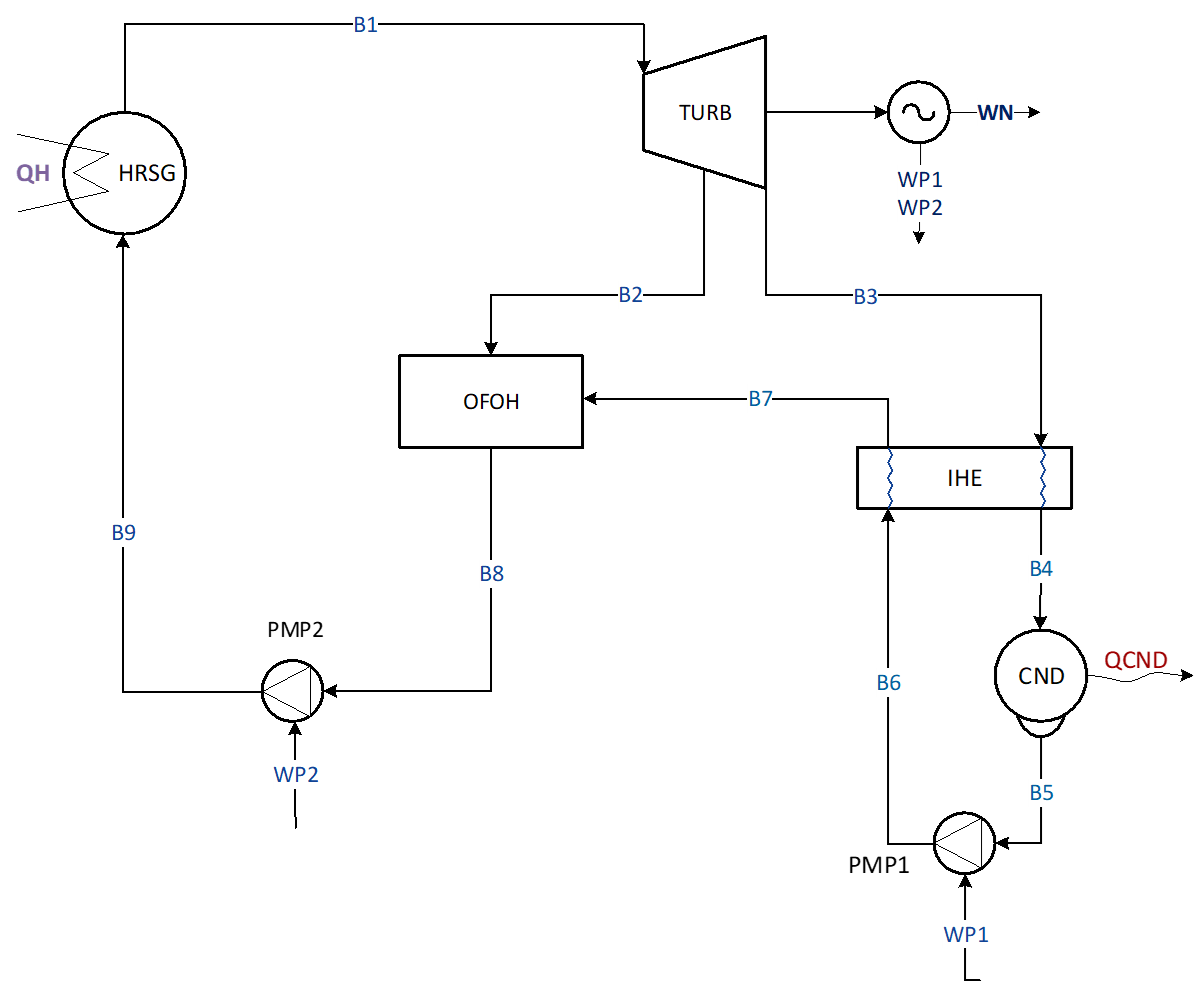

#### 1. Read the data model file

This function read the data model file and load it as a MATLAB object 

model=ThermoeconomicModel('rhorc_model.json');

INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [REF] are valid
INFO: cDataModel. Exergy values [EVP16] are valid
INFO: cDataModel. Exergy values [PCND2] are valid
INFO: cDataModel. Exergy values [PEXT05] are valid
INFO: cDataModel. Exergy values [ETA78] are valid
INFO: cExergyData. Process OFOH is not active
INFO: cDataModel. Exergy values [noEXT] are valid
INFO: cExergyData. Process IHE is not active
INFO: cExergyData. Process OFOH is not active
INFO: cDataModel. Exergy values [noIHE] are valid
INFO: cDataModel. Exergy values [CG] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. Resources Cost sample [External] is valid
INFO: cDataModel. Resources Cost sample [Internal] is valid
INFO: cDataModel. Data model rhorc_model is valid
INFO: cThermoeconomicModel. Productive Diagram Active
INFO: cThermoeconomicModel. Set state REF
INFO: cThermoeconomicModel. Compute Diagram FP
INFO: cThermoecon

setDebug(model,false);

#### 2. Show results for the REF case

Show the processes efficiency table

showResults(model,'eprocesses');


Processes Exergy Table - REF

Key         F(kW)      P(kW)      I(kW)     k(J/J)      η (%)
——————————————————————————————————————————————————————————————
HRSG        91.75      73.79      17.96     1.2434      80.43
TRB         65.43      53.76      11.67     1.2171      82.16
IHE          1.94       1.40       0.54     1.3857      72.16
OFOH         6.28       5.30       0.98     1.1849      84.39
PMP1         0.40       0.34       0.06     1.1765      85.00
PMP2         2.29       1.99       0.30     1.1508      86.90
GEN         53.76      52.69       1.07     1.0203      98.01
CND          9.17       9.17       0.00     1.0000     100.00
ENV         91.75      50.00      41.75     1.8350      54.50



Show the exergy cost of flows (table *dfcost*)

`Cost are decomposed into the part due to internal irreversibilities (kin*) and the cost due to wastes (kr*)`

showResults(model,'dfcost');


Flows Exergy Cost - REF

Key         B(kW)     B*(kW)   Bin*(kW)    Br*(kW)    k*(J/J)  kin*(J/J)   kr*(J/J)
————————————————————————————————————————————————————————————————————————————————————
B1          88.15     130.26     113.50      16.76     1.4777     1.2875     0.1902
B2           6.28       9.28       8.09       1.19     1.4777     1.2875     0.1902
B3          16.44      24.29      21.17       3.13     1.4777     1.2875     0.1902
B4          14.50      21.43      18.67       2.76     1.4777     1.2875     0.1902
B5           5.33       7.88       6.86       1.01     1.4777     1.2875     0.1902
B6           5.67       8.61       7.50       1.11     1.5185     1.3231     0.1954
B7           7.07      11.48      10.00       1.48     1.6233     1.4144     0.2089
B8          12.37      20.76      18.09       2.67     1.6780     1.4621     0.2159
B9          14.36      24.96      21.75       3.21     1.7381     1.5144     0.2237
QH          91.75      91.75      91.75       0.0

Show the irreversibilty-cost graph (table* dict*)

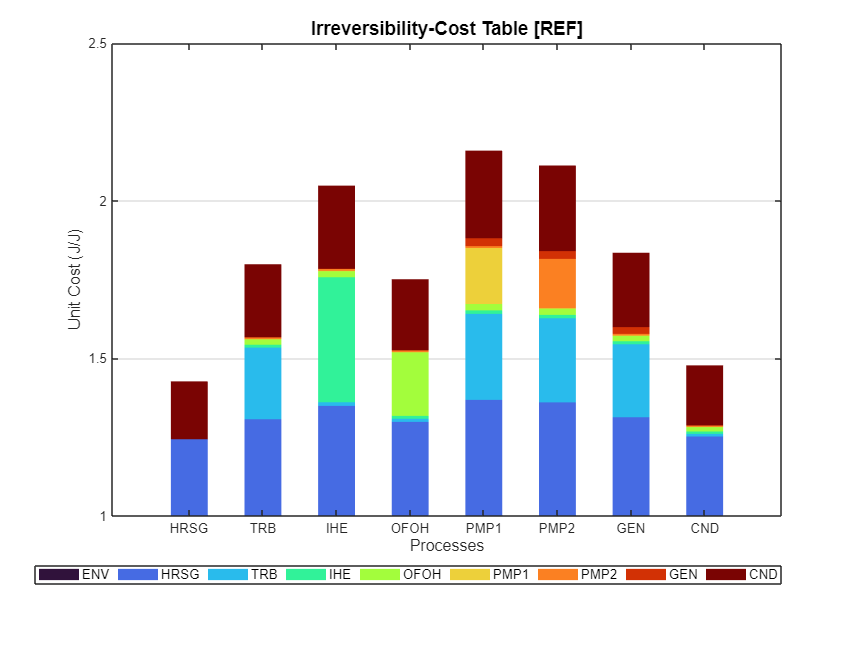

showGraph(model,'dict');

`This graph shows the cost of processes and the contribution of the irreversibilities of each process.`

#### 3. Compare the different plant simulations

Show the exergy cost of flows (table *dfuc*)

setSummary(model,'STATES');
showResults(model,'dfuc');


Flows Direct Unit Exergy Cost (J/J) - SUMMARY

 key           REF     EVP16     PCND2    PEXT05     ETA78     noEXT     noIHE        CG
—————————————————————————————————————————————————————————————————————————————————————————
 B1         1.4777    1.5246    1.5357    1.4856    1.4810    1.5455    1.6480    1.9246
 B2         1.4777    1.5246    1.5357    1.4856    1.4810    1.5455    1.6480    1.9246
 B3         1.4777    1.5246    1.5357    1.4856    1.4810    1.5455    1.6480    1.9246
 B4         1.4777    1.5246    1.5357    1.4856    1.4810    1.5455    1.6480    1.9246
 B5         1.4777    1.5246    1.5357    1.4856    1.4810    1.5455    1.6480    1.9246
 B6         1.5185    1.5653    1.5743    1.5202    1.5243    1.5878    1.6931    1.9632
 B7         1.6233    1.6592    1.6675    1.6286    1.6365    1.6995    1.6931    2.0059
 B8         1.6780    1.7314    1.7099    1.6653    1.6820    1.6995    1.6931    2.0387
 B9         1.7381    1.7787    1.7766    1.7351    1.7491   

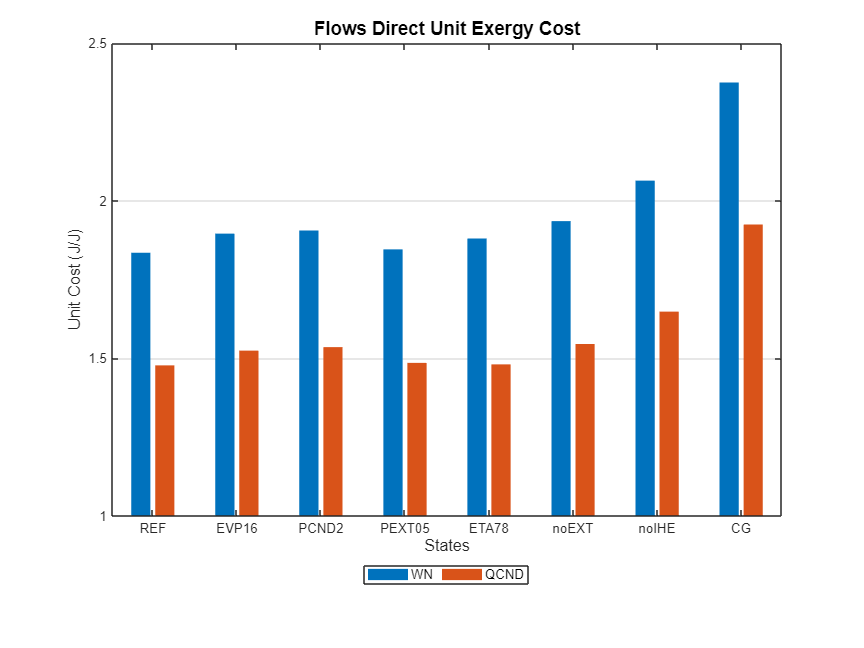

showGraph(model,'dfuc');

#### 4. Compare States. Thermoeconomic Diagnosis

Compare REF state with CG (Increase condenser temperature for cogeneration)

setState(model,'CG');
summaryDiagnosis(model);

Fuel Impact:         26.980 (kW)
Technical Saving:    26.980 (kW)



showResults(model,'dgn');


Diagnosis Summary - CG

Key        MF(kW)     ΔI(kW)     ΔR(kW)    ΔPt(kW)    MF*(kW)    MR*(kW)   ΔPt*(kW)
————————————————————————————————————————————————————————————————————————————————————
HRSG       -2.187      2.950      0.000      0.000     -2.187      0.000      0.000
TRB        -0.422     -0.240      0.000      0.000     -0.321      0.000      0.000
IHE        -0.362     -0.140      0.000      0.000     -0.444      0.000      0.000
OFOH       -0.500     -0.230      0.000      0.000     -0.603      0.000      0.000
PMP1       -0.005      0.030      0.000      0.000     -0.008      0.000      0.000
PMP2       -0.008      0.070      0.000      0.000     -0.012      0.000      0.000
GEN         0.003      0.020      0.000      0.000      0.004      0.000      0.000
CND         0.000      0.000     24.520      0.000      0.029     30.522      0.000
ENV        -3.481      2.460     24.520      0.000     -3.542     30.522      0.000



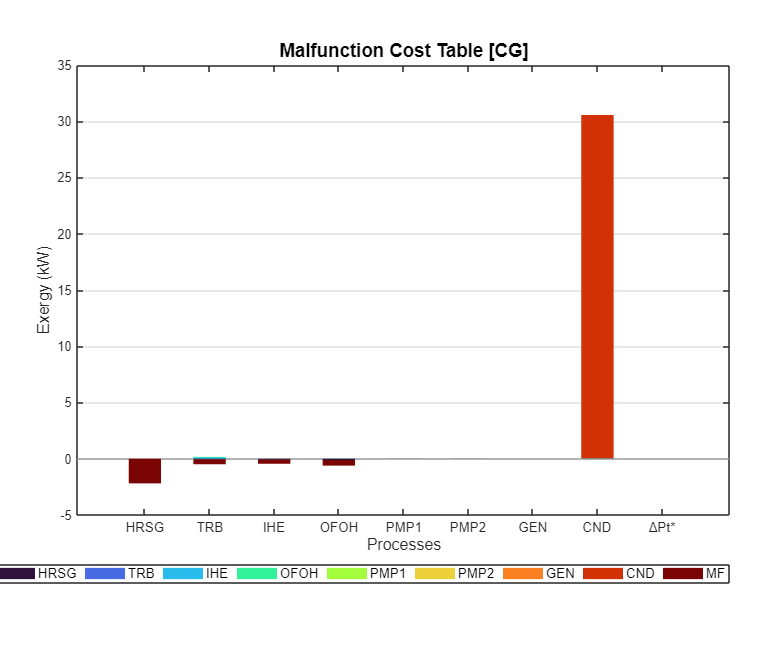

showGraph(model,'mfc');

`In this case we consumed 26.98 kW of additional resources due mainly to the condenser losses.`

#### 5. Analize Recycling Condenser Heat

Define the active waste and analyze the recycling (table *rad*)

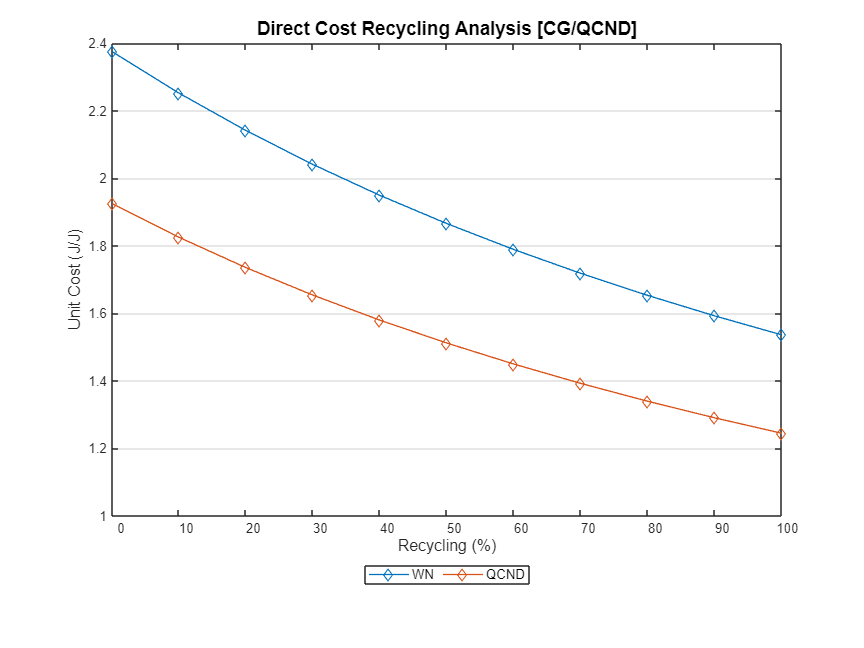

setActiveWaste(model,'QCND');
setRecycling(model,true);
showGraph(model,'rad');

`Comparing with the unit cost of electricity (WN) in the REF state, if we recycled more than the 60% of heat, electricity cost is cheaper.`

setWasteRecycled(model,0.6);
summaryDiagnosis(model);

Fuel Impact:         26.980 (kW)
Technical Saving:    -2.890 (kW)



showResults(model,'dgn');


Diagnosis Summary - CG

Key        MF(kW)     ΔI(kW)     ΔR(kW)    ΔPt(kW)    MF*(kW)    MR*(kW)   ΔPt*(kW)
————————————————————————————————————————————————————————————————————————————————————
HRSG       -2.187      2.950      0.000      0.000     -2.187      0.000      0.000
TRB        -0.422     -0.240      0.000      0.000     -0.321      0.000      0.000
IHE        -0.362     -0.140      0.000      0.000     -0.444      0.000      0.000
OFOH       -0.500     -0.230      0.000      0.000     -0.603      0.000      0.000
PMP1       -0.005      0.030      0.000      0.000     -0.008      0.000      0.000
PMP2       -0.008      0.070      0.000      0.000     -0.012      0.000      0.000
GEN         0.003      0.020      0.000      0.000      0.004      0.000      0.000
CND         0.000      0.000      4.306     20.214      0.029      1.220     29.302
ENV        -3.481      2.460      4.306     20.214     -3.542      1.220     29.302



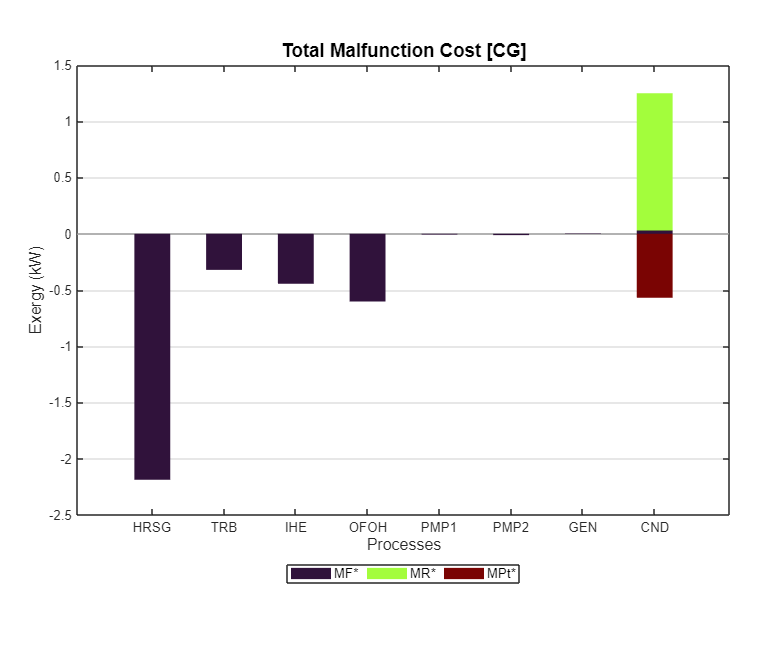

ShowGraph(model,'Graph','tmfc');

ShowResults(model,'Table','tmfc');


Total Malfunction Cost (kW) - CG

 key           MF*       MR*      MPt*     Total
—————————————————————————————————————————————————
 HRSG       -2.187     0.000     0.000    -2.187
 TRB        -0.321     0.000     0.000    -0.321
 IHE        -0.444     0.000     0.000    -0.444
 OFOH       -0.603     0.000     0.000    -0.603
 PMP1       -0.008     0.000     0.000    -0.008
 PMP2       -0.012     0.000     0.000    -0.012
 GEN         0.004     0.000     0.000     0.004
 CND         0.029     1.220    -0.568     0.680
 ENV        -3.542     1.220    -0.568    -2.890



`We still consume 26.98 kW of additional resources, but we are reducing waste from 24 to 4 kW and producing 20 of additional heat. Malfunctions are reduced in 3.5 kW and there is a  technical saving of 2.89 kW.`